# Transfer Learning Using AlexNet

In Lab 8, you will implement a new CNN model to classify the object types using transferring learning technology. The 2012 ImageNet competition-winning algorithm, AlexNet, achieved the highest classification performance at that time. It was trained with over 1.4M image samples and classified 1000 object categories. In addition, the network has learned rich feature representations for a wide range of images. 

The architecture of AlexNet contains 5 convolutional layers and 3 fully connected layers, as shown below:

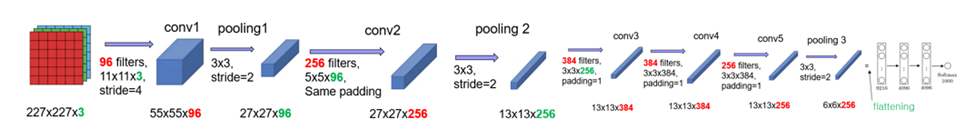

Transfer learning takes CNN layers from a pre-trained network trained on an extensive data set. The advantage of transfer learning is that it utilizes a rich set of features learned in the pre-trained network. These features can be fine-tuned using a smaller new data set and applied to similar tasks. In Lab 8, you will implement an image classification system using transfer-learning technology. The classification system will classify three objects: {Cat, Dog, Car}.  

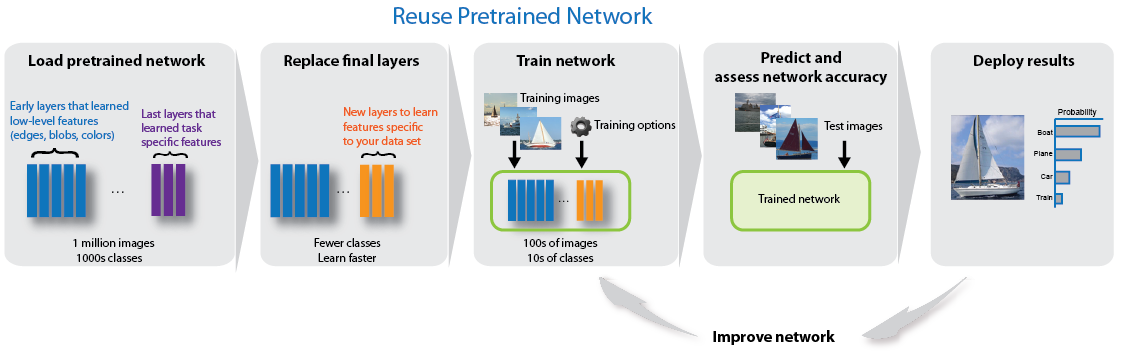

# 1) Load the new Image Data using the function, **imageDatastore**()

The provided dataset contains 3,000 color images in three categories {‘dog’, ‘cat’, ‘car’}. The folder structure of the image dataset is presented below. There are three subfolders, and each folder name corresponds to the target class label. 

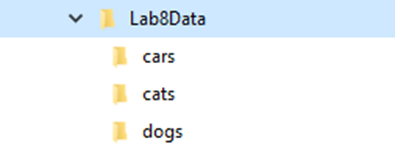

There are three subfolders; each folder name corresponds to the target class label. For example, 

- 1000 car image samples in the ‘cars’ folder.

- 1000 cat image samples in the ‘cats’ folder.

- 1000 dog image samples in the ‘dogs’ folder.

The function **imageDatastore**() automatically labels the images based on folder names and stores the data as an ImageDatastore object.   

**EX: **

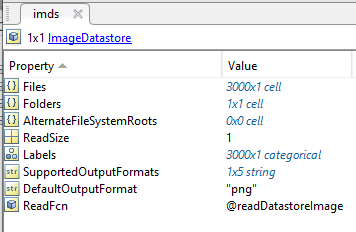         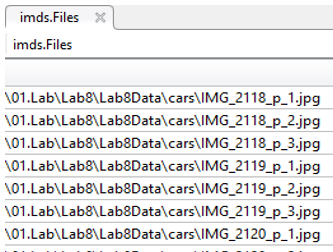         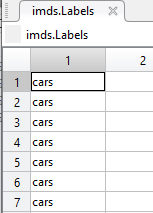

clear all;  

%a) Using the function imageDatastore(), create an ImageDatastore object that contains all image file locations and the corresponding target labels.
% See the documents for the details.

imds = imageDatastore('Lab8Data','IncludeSubfolders',true,...
    'LabelSource','foldernames');



Cont. 

Get the information about the number of samples per class using the function **countEachLabel(). ** 

Display the number of samples per class in the provided data.  

`Usage: countEachLabel(mmm) `     `% mmm is your variable name for the imageDatastore object in Task 1-a). `


% b)Using the function countEachLabel(), display the number of samples per class in the provided data. 

countEachLabel(imds)

ans = 3×2 table
    Label    Count
    _____    _____

    cars     1000 
    cats     1000 
    dogs     1000 


# 2)  Split the data

The provided dataset is divided into training, validation, and test data sets. You will use 60% of images per category to train, 20% for validation, and specify 20% as a test set. The function **splitEachLabel**() splits the ImageDatastore data samples according to specified label proportions. See the documentation for the details about the **splitEachLabel**() function. 

`ex) [`tr_`imds``, `val_imds`, `te_imds`] = ``splitEachLabel``(imds,0.6,0.2,0.2, ``'randomized'``);     % create three `**imageDatastore**  objects

`  %  `imds  :` your variable name for the `**imageDatastore**  object for the whole data samples in Task1 -a)

    % tr_`imds`:  `your variable name for the `**imageDatastore**  object for the training data samples

    %  val_imds:  `your variable name for the `**imageDatastore**  object for the validation data samples

    %  te_imds :  `your variable name for the `**imageDatastore**  object for the testing data samples

%a) Using the splitEachLabel() function, create three imageDatastore  object for training, testing, and validation sets.

[tr_imds, val_imds, te_imds] = splitEachLabel(imds,0.6,0.2,0.2, 'randomized'); 

%b) Using the function countEachLabel(), display the count for each category in the training data set generated in Task 2-a).

countEachLabel(tr_imds)

%c) Using the function countEachLabel(), display the count for each category in the validation data set generated in Task 2-a).

countEachLabel(val_imds)
 

%d) Using the function countEachLabel(), display the count for each category in the testing data set generated in Taks 2-a).
  
countEachLabel(te_imds) 

# 3) Visualize  the Data

Display the randomly selected 16 image samples from the training dataset.  

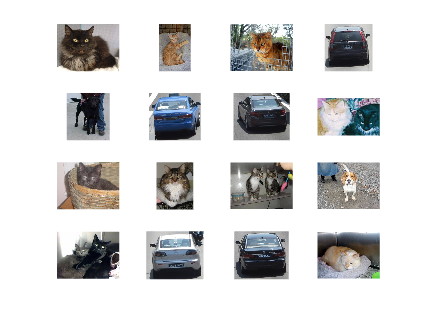

%a) Find the number of samples in the training data using length(). 
% ex: nnn = length(xxx.Labels)         % xxx is your variable name for the training dataset in Task 2-a) 



TrainLen = length(tr_imds.Labels);


% In the for-loop below, randomly select image from the training dataset will be displayed:  
 figure
 for i = 1:16
     subplot(4,4,i)
 
     %b) Select one sample index from the training data set using the function randperm(). 
     %  1st parameter: total number of the samples in training dataset
     % 2nd parameter: 1

     RandIdx = randperm(TrainLen,1);          

     %c) read the image in the training data using the function 'readimage()'.
     % ex: --- = readimage( xxx, idx); 
    
      % xxx  : your variable name for the training dataset in Task 2-a) 
      % idx  : your variable name for the ith sample index generated in Task3-b) 
      % ---  : your variable name for the image data 
       
      imgData = readimage(tr_imds,RandIdx);


      
      %d) display the selected image using the function imshow()
      % ex) imshow(---)            % ---  : your variable name for the selected image created in Task3 -c)

        imshow(imgData);
    
 end

% 




# **4) Load the pre-trained Alex Network**

AlexNet is trained on more than one million images and classified 1000 different object categories. In addition, the AlexNet model contains rich feature representations for a wide range of images. 

Load the pre-trained AlexNet network using the command below:

net = alexnet;

If Neural Network Toolbox™ Model *for AlexNet Network* is not installed, the below error message will be displayed

                              

 By clicking the provided link, “Add-on Explorer”, you can install the software.

%a) load the pre-trained Alexnet into the Matlab workspace and save it into the variable name you defined
% ex) net = alexnet;

net = alexnet; 

% If Neural Network Toolbox™ Model for AlexNet Network is not installed, the error message will be displayed .  
% By clicking the provided link, "Add-on Explorer", you can install the pre-trained Alexnet.
%b) Display the network architecture by typing the below:
%   net.Layers              % net is your variable name generated for the AlexNet in Task 4 -a) 

net.Layers

ans =   25×1 Layer array with layers:

     1   'data'     Image Input                   227×227×3 images with 'zerocenter' normalization
     2   'conv1'    2-D Convolution               96 11×11×3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    2-D Max Pooling               3×3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    2-D Grouped Convolution       2 groups of 128 5×5×48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    2-D Max Pooling               3×3 max pooling with stride [2  2] and padding [0  0  0


%c)The pre-trained AlexNet model was trained with images of 227x227x3, but the new training images have different sizes. 
% The first layer in the AlexNet is the image input layer. Find out the input image size in the Alexnet. 
% Create a new variable that holds the size of the input image used in AlexNet.
% ex)  ssss = net.Layers(1).InputSize           % net : your variable name generated for the AlexNet in Taks 4-a) 
                                                % Layer(1) means the first layer
                                                % Layers(1).InputSize means the input size in the 1st Layer
                                                % ssss: your variable name for the image input size used in Alex net.


InSize = net.Layers(1).InputSize;


# **5. **Image Resize 

The pre-trained **AlexNet **model was trained with images of the size **227x 227x3**, but the new training images have different sizes. Use the function **augmentedImageDatastore**() to **resize **the new training images with the same size of images used in AlexNet. 

% a) Resize the training dataset using augmentedImageDatastore() 
%  rrr =  augmentedImageDatastore(ssss, tr_imds);       % ssss: your variable for the AlexNet input size defined in Task 4-c)
                                                        % tr_imds: your variable name for the training dataset in Task2-a)
                                                        % rrr : your variable name for the resized training dataset for training 
                                                           

TrainRs = augmentedImageDatastore(InSize,tr_imds);   

% b) Similarly, resize the validation dataset,val_imds, using augmentedImageDatastore()  
% val_imds: your variable name for the validation dataset in Task 2-a)

ValRs = augmentedImageDatastore(InSize,val_imds);     


% c) Similarly, resize the test dataset,te_imds, using augmentedImageDatastore() 
% te_imds :your variable name for the testing dataset in Task 2-a)

TestRs = augmentedImageDatastore(InSize,te_imds);   
 

# **6. Re****place the Final Layers**

The last few layers in the pre-trained AlexNet are designed to classify 1000 objects. However, we need to classify different objects now.  The first step in transfer learning is to replace the last few layers of the pre-trained network with a set of layers that can classify the number of classes in your task. Specify the options of the new fully connected layer according to the new data. Set the fully connected layer to have the same size as the number of classes in the new data.

In Lab 8, the knowledge in Layer 1 to Layer 22 in the pretrained Alex net will be used by transfer learning.  Thus, the last three layers will be replaced with your designed layers. Those three layers are a fully connected layer, a softmax layer, and a classification output layer. These three layers must be fine-tuned using the new training data samples for the new classification task. 

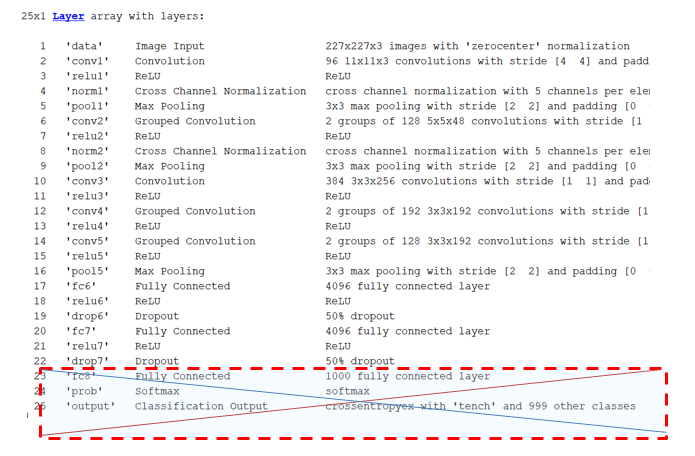

%a) Create a new variable that contains layers from layer 1 to layer 22 in the AlexNet. 
% ex)  ttt = net.Layers(1:22)                 % net: your variable name for the Alexnet in Task 4-a)
                                              % ttt: your variable name for layers 1 to 22 in the AlexNet. 

                            
Layers = net.Layers(1:22);
   
%b)Using the function fullyConnectedLayer(), create a fully connected layer with 3 nodes (the number of classes in the new data) and save it into a new variable . 
%  

f1 = fullyConnectedLayer(3);

%c) Create a softmax layer using the function,softmaxLayer().
% A softmax layer applies a softmax function to calculate the probability of a particular label over k different labels. 
%ex) sm =softmaxLayer;

sm =softmaxLayer;



%d) Create the final classification layer using the function, classificationLayer.
%ex:  outlayer= classificationLayer;

outlayer= classificationLayer;

%e) Create a new CNN architecture by combining 
%    i)   layers  created in Task 6-a) : Alexnet from layer 1 to layer 22
%    ii)  a fully connected layer defined in Task 6-b)
%    iii) a Softmax Layer defined in Task 6-c)
%    iv)  a classification Layer defined in Task 6-d).


new_CNN = [ 
           Layers           %i)   layers  created in Task 6-a) : Alexnet from layer 1 to layer 22
           f1               %ii)  a fully connected layer defined in Task 6-b)
           sm               %iii) a Softmax Layer defined in Task 6-c)
           outlayer         %iv)  a classification Layer defined in Task 6-d).
          ];
%







# **7. Train the new DNN model**

Now that the network architecture is defined in Task 6 -e). It can be trained using the new training data. First, specify the training options using the function [**trainingOptions**](https://www.mathworks.com/help/nnet/ref/trainingoptions.html)(). 

- To keep the features in the early layers of the pre-trained network (the transferred layer weights) and slow down learning in those layers, thus the initial learning rate is set to a small value. 

- An epoch is a complete training cycle on the entire training data set. You do not need to iterate many epochs when performing transfer learning because rich features are already learned in the pre-trained CNN. 

- The mini-batch size is the amount of data included in each sub-epoch weight change. Specify the mini-batch size and validation data. 

Below is an example of a training option. See the Matlab document for the details. 

`options = trainingOptions('sgdm'``, ``...`

    `'MiniBatchSize', ``10, ``...`

    `'MaxEpochs'``,10, ``...`

    `'InitialLearnRate'``,1e-4, ``...`

    `'Shuffle'``,``'every-epoch'``, ``...`

    `'ValidationData'``,  ``Resized_ValData``, ``...`

    `'ValidationFrequency'``,3, ``...`

    `'Verbose'``,false, ``...`

    `'Plots'``,``'training-progress'``);`

`Note: ``Resized_ValData           %``your variable name for the resized validation data set in Task 5-b)`

The network training algorithm uses Stochastic Gradient Descent with an initial learning rate of 0.0001. The training algorithm iterated 10 epochs. 

%a) add code for the network training options. See the above explanation for training options. 

options = trainingOptions('sgdm', ...
    'MiniBatchSize', 10, ...
    'MaxEpochs',10, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',  ValRs, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress')

options =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-04
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 10
                   MiniBatchSize: 10
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: [1×1 augmentedImageDatastore]
             ValidationFrequency: 3
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
                      WorkerLoad: []
        

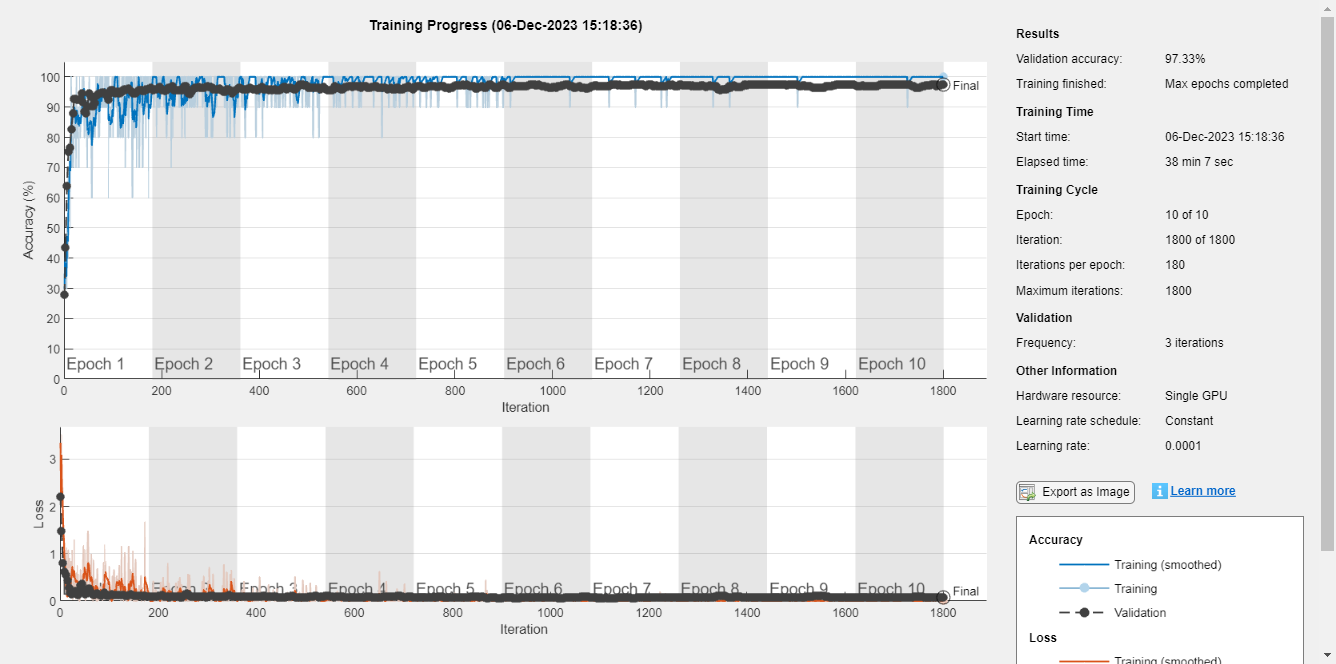




%b) Train the network using the function trainNetwork()  
%The parameters for the function trainNetwork() are 
%   i)   the resized training data in Task 5-a), 
%   ii)  the new CNN architecture in Task 6-e) , 
%   iii) training options in Task 7-a). 

%ex) NNN = trainNetwork(  resized training data defined in Task 5-a), new cnn architecture in Task 6-e),  training options in 7-a) ) 
% NNN: your variable name for the trained model


newNet = trainNetwork(TrainRs,new_CNN,options);



% If you get an out-of-memory error, consider changing the 'MiniBatchSize' to a lower value in 7-a).
disp("Initialization may take up to a minute before training begins")

Initialization may take up to a minute before training begins



 

%Note: The training will take about 15-20 min.


# **8. Evaluation of the trained DNN model on the Testing Data Set**

After the CNN training is completed, the CNN model should be evaluated to ensure that the CNN model training is successful. To evaluate the trained model, the test data set  is used to measure the trained DNN model's classification accuracy.  The goal of this example is not necessary to achieve 100% accuracy of the CNN model on the test set but sufficient to apply the trained model as an object classifier.

%a) Evaluate the trained network on the test set using the function, classify()
% xxxx = classify( your trained network variable name in Task 7-b),  the variable name for the re-sized test data in Task 5-c); 
%the output xxxx contains the predicted categorical output.


out = classify(newNet,TestRs);

%b) Create a variable to hold the ground truth labels for the testing dataset. 
%  ex) YTest = te_imds.Labels;         %te_imds : your variable name for the test dataset in Task 2-a)


YTest = te_imds.Labels;




% c) Calculate the accuracy of the trained CNN model on the testing data
% if the predicted  label is equal to the true label, then it is correct.  if not incorrect. 
% You can compare the predicted result in Task 8-a) with the ground truth variable created in Task 8-b) 


TestAccuracy =  sum( out == YTest) / length(YTest)

TestAccuracy = 0.9683

# 9. Demo - Display the selected Input Images and Predicted  Results.

% a) Get the number of samples in the testing dataset using the function length().
%   ex: m2=length( te_imds.Labels);         %te_imds : your variable name for the test dataset in Task 2-a)  

m2=length( te_imds.Labels);

m2 = 600

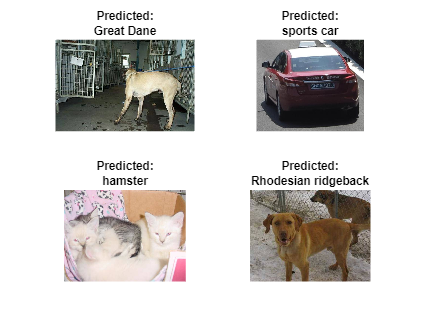




 figure
 for i = 1:4

     subplot(2,2,i)
 

      %b) Select one sample index from the testing data samples using the function randperm(). 
      % 1st parameter: total number of the samples in the testing data
      % 2nd parameter: 1

       
     newRand = randperm(m2,1); 

     

     %c) Using the sample index selected in Step 9-b), extract the image data. 
     %  Use the function readimage(), read the image in the imageDatastore object
     % ex: img = readimage( xxx, rand_index); 
    
      % xxx is your variable name of the testing dataset in Task2-a) 
      % rand_index; your variable name in Step 9-b)
      % img is your variable name for the selected image data 


     img = readimage( te_imds, newRand); 



     %d) resize the image with the size used in the CNN model using the function imresize()
     %  ex: resized_img = imresize( img,  [227, 227] )             % img:  your variable name in Step 9-c)


    resized_img = imresize( img,  [227, 227] );


     % e) using the trained CNN model in Task 7-b), make a prediction for the resized image generated in Step 9-d) 
     % ex: aaa = classify (net,  resized_img);          % net: the trained net in Task 7-b). 
                                                        % resized_img: your variable name for the selected image generated in Step 9-d) 

     pred = classify (net,  resized_img);

     


     % f) use the function string() to convert the predicted label in e) into a string.
    
        
    PredS = string(pred);
    
   
     %g)Use the function title() to display the string you converted in f).
     %  Display the input image and the prediction: 
     % Uncomment below and provide your variable names in char() function.
     %     
          imshow( img)                            % img: the selected image generated in Step 9-c) 
          title([' Predicted: '  pred ])           %ttt : your variable name in Step 9-f)
       
       


  
                                                                         


 end